fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'TestRumori', '');
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'cat_michele.jpg';
folderPath = fullfile(folderPath, nome_img);

i2 = imread(folderPath);
i_double = im2double(i2);

% 2. Aggiungi rumore speckle
j = imnoise(i_double, "speckle", 0.01);

% 3. Prealloca immagine filtrata
j_filtered = zeros(size(j));

% 4. Applica filtro Wiener canale per canale (finestra 5x5)
for c = 1:3
    j_filtered(:,:,c) = wiener2(j(:,:,c), [3 3]);
end

% 5. Calcola PSNR
psnr_noisy = psnr(j, i_double);
psnr_filtered = psnr(j_filtered, i_double);

% 6. Visualizza risultati
fprintf("PSNR immagine rumorosa: %.2f dB\n", psnr_noisy);

PSNR immagine rumorosa: 25.55 dB


fprintf("PSNR dopo filtro Wiener: %.2f dB\n", psnr_filtered);

PSNR dopo filtro Wiener: 32.28 dB


fprintf("PSNR dopo filtro Lee: %.2f dB\n", psnr_lee);

PSNR dopo filtro Lee: 29.53 dB


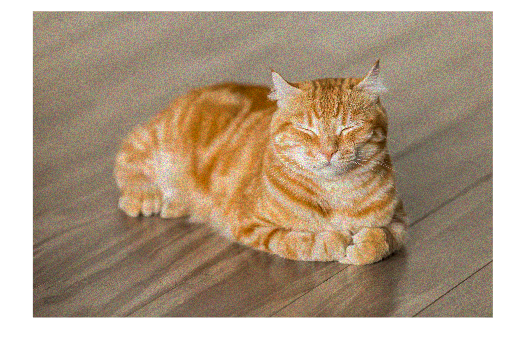


imshow(j);

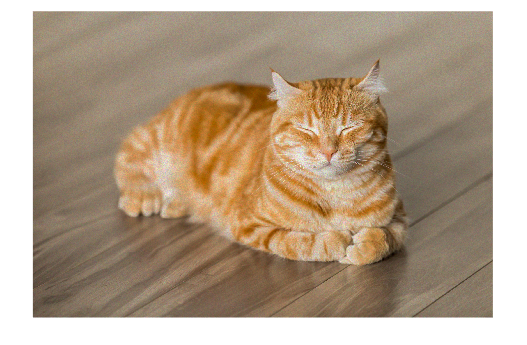

imshow(j_filtered);

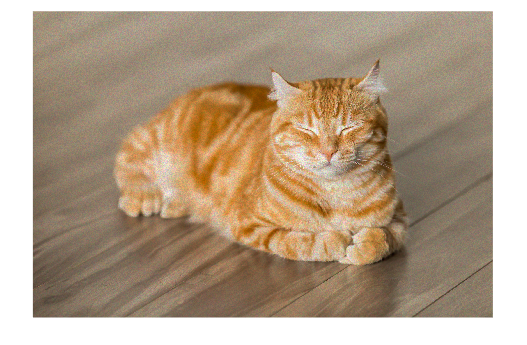


lee_filtered = Lee_filter(j,9);
imshow(lee_filtered)

double_lee = im2double(lee_filtered);
psnr_lee = psnr(double_lee, i_double);